% =========================================================================
%     LAPLACE SOLVER FOR CORNER SINGULARITIES VIA RATIONAL FUNCTIONS
% =========================================================================
% A comprehensive test suite of 6 challenging domains designed to 
% demonstrate the efficacy of clustering poles near singularities 
% compared to standard polynomial basis methods.

clear all; close all; clc;

% =========================================================================
% EXAMPLE 1: The Pinched Diamond
% Type:          Non-Convex
% Boundary Data: Logarithmic singularity (-log|z|)
% Challenge:     Introduces symmetric re-entrant (inward-pointing) corners 
%                that require denser pole clustering to resolve.
% =========================================================================
disp('--> Example 1: Pinched Diamond')

--> Example 1: Pinched Diamond


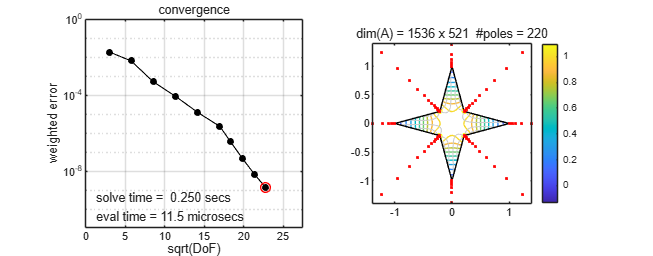


z = 0.3 * exp(0.25i * pi);
P = [1, z, 1i, 1i*z, -1, -z, -1i, -1i*z];
h = @(z) -log(abs(z));

laplace(P, h, 'tol', 1e-8, 'rel');

subplot(1,2,1)
xlim([-8.9768e-02, 2.7529e+01])
ylim([1.0792e-11, 1.0792e+00])
zlim([-1.0000e+00, 1.0000e+00])



% =========================================================================
% EXAMPLE 2: The Wedding Cake
% Type:          Non-Convex
% Boundary Data: Distance from a point above the domain (|z - 5i|)
% Challenge:     Multiple 90-degree and 270-degree corners in a staggered, 
%                highly asymmetric arrangement.
% =========================================================================
disp('--> Example 2: Wedding Cake')

--> Example 2: Wedding Cake


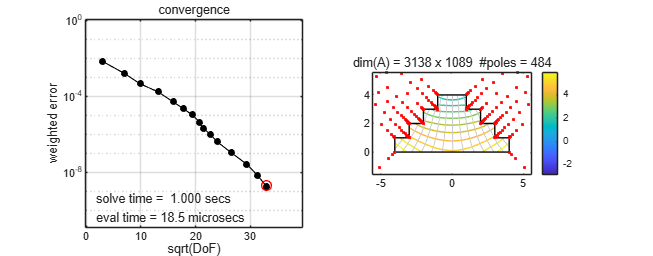


P = [4, 4+1i, 3+1i, 3+2i, 2+2i, 2+3i, 1+3i, 1+4i, ...
    -1+4i, -1+3i, -2+3i, -2+2i, -3+2i, -3+1i, -4+1i, -4];
h = @(z) abs(z - 5i);

laplace(P, h, 'tol', 1e-8, 'rel');

subplot(1,2,1)
xlim([-2.4095e-01, 3.9689e+01])
ylim([1.2447e-11, 1.2447e+00])
zlim([-1.0000e+00, 1.0000e+00])



% =========================================================================
% EXAMPLE 3: Asymmetric Starburst
% Type:          Non-Convex
% Boundary Data: High-frequency trigonometric wave (cos(3x)*sin(3y))
% Challenge:     Severe, acute asymmetric corner singularities combined with 
%                oscillatory boundaries requiring highly dense pole clustering.
% =========================================================================
disp('--> Example 3: Asymmetric Starburst')

--> Example 3: Asymmetric Starburst


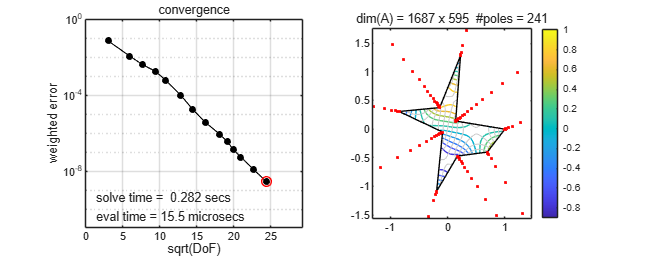


angles = [0, 45, 80, 110, 160, 210, 260, 290, 330] * (pi/180);
radii  = [1.0, 0.2, 1.3, 0.4, 0.9, 0.1, 1.1, 0.5, 0.8];

P = radii .* exp(1i * angles);
h = @(z) cos(real(z)*3) .* sin(imag(z)*3);

laplace(P, h, 'tol', 1e-8, 'rel');

subplot(1,2,1)
xlim([-1.3250e-01, 2.9383e+01])
ylim([1.0775e-11, 1.0775e+00])
zlim([-1.0000e+00, 1.0000e+00])



% =========================================================================
% EXAMPLE 4: Pinched Bowtie
% Type:          Non-Convex
% Boundary Data: Parabolic bowl simulating distance squared (|z|^2)
% Challenge:     A mathematically aggressive, narrow choke point connecting 
%                two large regions. Severely stresses the smooth Runge 
%                (polynomial) basis. Tolerance loosened due to ill-conditioning.
% =========================================================================
disp('--> Example 4: Pinched Bowtie')

--> Example 4: Pinched Bowtie


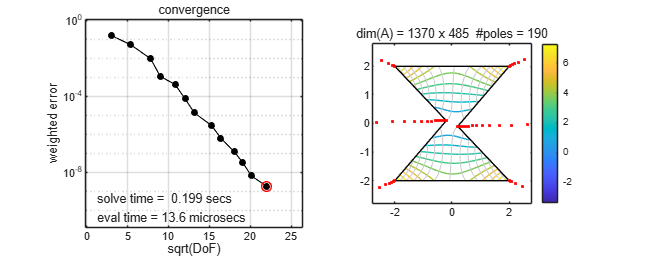


P = [-2-2i, 2-2i, 0.2-0.1i, 2+2i, -2+2i, -0.2+0.1i];
h = @(z) abs(z).^2;

laplace(P, h, 'tol', 1e-8, 'rel');

subplot(1,2,1)
xlim([-2.0614e-01, 2.6441e+01])
ylim([1.2596e-11, 1.2596e+00])
zlim([-1.0000e+00, 1.0000e+00])



% =========================================================================
% EXAMPLE 5: The Diamond
% Type:          Convex
% Boundary Data: Logarithmic singularity (-log|z|)
% Challenge:     Serves as the baseline test for acute, salient corners.
% =========================================================================
disp('--> Example 5: Diamond')

--> Example 5: Diamond


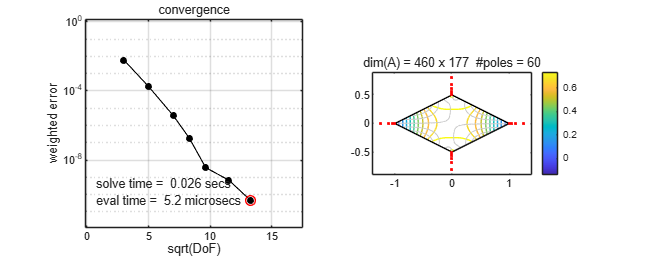


P = [1, 0.5i, -1, -0.5i];
h = @(z) -log(abs(z));

laplace(P, h, 'tol', 1e-10 , 'rel');

subplot(1,2,1)
xlim([-1.6204e-01, 1.7546e+01])
ylim([1.1573e-12, 1.4569e+00])
zlim([-1.0000e+00, 1.0000e+00])


% =========================================================================

% =========================================================================
%     LAPLACE SOLVER FOR CORNER SINGULARITIES VIA RATIONAL FUNCTIONS
% =========================================================================
function [u, maxerr, f, Z, Zplot, A, v] = laplace(P, varargin) 
%% Set up the problem
[g, w, ww, pt, dw, tol, steps, plots, ...        % parse inputs
    slow, rel, arnoldi, aaaflag] = ...
    parseinputs(P,varargin{:});
Zplot = ww;                                        
nw = length(w);                                  % number of corners
wr = sort(real(ww)); wr = wr([1 end]);
wi = sort(imag(ww)); wi = wi([1 end]);
wc = mean(wr+1i*wi);                             % for scale- and transl-invariance
scl = max([diff(wr),diff(wi)]);
q = .5; if slow == 1, q = 0; end                 % sets which corners get more poles
inpolygonc = @(z,w) inpolygon(real(z), ...
            imag(z),real(w),imag(w));            % complex variant of "inpolygon"
for k = 1:nw
   forward = pt{k}(.01*dw(k)) - w(k);            % small step toward next corner
   j = mod(k-2,nw)+1;                             
   backward = pt{j}(.99*dw(j)) - w(k);           % small step toward last corner
   tmp = 1i*backward*sqrt(-forward/backward);
   outward(k) = tmp/abs(tmp);                    % outward direction from corner
end
warn = warning('off','MATLAB:rankDeficientMatrix');  % matrices are ill-conditioned

%% Set up for plots
if plots
   LW = 'linewidth'; MS = 'markersize'; FS = 'fontsize';
   fs = 9; PO = 'position'; FW = 'fontweight'; NO = 'normal';
   sx = linspace(wr(1),wr(2),100); sy = linspace(wi(1),wi(2),100);
   [xx,yy] = meshgrid(sx,sy); zz = xx + 1i*yy;
   ax = [wr(1:2); wi(1:2)] + .2*scl*[-1 1 -1 1]';
   axwide = [wr(1:2); wi(1:2)] + 1.1*scl*[-1 1 -1 1]';
end
if steps
   clf, subplot(1,2,1), shg, plot(w([1:end 1]),'k',LW,1)
   grid on, axis equal, axis(axwide)
end

%% Main loop: increase number of poles until convergence ==============================
Nvec = []; errvec = []; tic
errk = ones(nw,1);                               % max error near each corner
nkv = zeros(nw,1);                               % no. of poles at each corner
maxstepno = 30; err0 = Inf;
  
for stepno = 1:maxstepno
   % Fix poles and sample pts on bndry.  Side k means side from corner k to k+1.
   Z = [];           % col vector of sample points on boundary
   G = [];           % col vector of boundary values at these points
   T = [];           % col vector of unit tangent vectors at these points
   pol = [];         % row vector of poles of the rational approximation
   J = [];           % row vector of indices of which corner each pole belongs to
   d = [];           % row vector of distances from poles to their corners
   tt = cell(nw,1);  % cell array of distances of sample points along each side
   for k = 1:nw
      nk = nkv(k);                                  % no. of poles at this corner
      sk = sqrt(1:nk) - sqrt(nk);
      dk = exp(4*sk); dk = scl*dk;                  % stronger clustering near corner
      dk = dk(dk>1e-15*scl);                        % remove poles too close to corner
      polk = w(k) + outward(k)*dk;                  % poles near this corner
      ii = find(inpolygonc(polk(dk>1e-12*scl),ww),1); % work around inaccuracy
      if length(ii)>0                               % don't allow poles in Omega
          dk = dk(1:ii-2); polk = polk(1:ii-2);
      end
      pol = [pol polk]; d = [d dk];
      J = [J k*ones(1,length(dk))];
      dvec = [(1/3)*dk (2/3)*dk dk];                % finer pts for bndry sampling
      tt{k} = [tt{k} dvec(dvec<dw(k)) ...           % add clustered pts near corner
          linspace(0,dw(k),max(30,nk))];            % additional pts along side
      j = mod(k-2,nw)+1;                            % index of last corner
      tt{j} = [tt{j} dw(j)-dvec(dvec<dw(j))];       % likewise in other direction
   end
   for k = 1:nw
      tt{k} = sort(tt{k}(:));
      tk = tt{k}; pk = pt{k};                       % abbrevations 
      Z = [Z; pk(tk)];                              % sample pts on side k
      G = [G; g{k}(pk(tk))];                        % boundary data at these pts
      h = 1e-4;                                     % 4-pt trapezoidal rule
      T = [T; (pk(tk+h)-1i*pk(tk+1i*h) ...
             - pk(tk-h)+1i*pk(tk-1i*h))/(4*h);];    % unnormalized tangent vectors
   end
   T = T./abs(T);                                   % normalize tangent vectors
   II = isnan(G);                                   % Neumann indices
   if any(II), arnoldi = 0; end
  
   % Solve the Laplace problem
   n = 4*stepno;                                    % degree of polynomial term
   Np = length(pol);

   M = size(Z,1);
   H = zeros(n+1,n);                                % Arnoldi Hessenberg matrix
   if arnoldi == 1               
      Q = ones(M,1);                                % cols of Q have norm sqrt(M)
      for k = 1:n                                   % Arnoldi process
         v = (Z-wc).*Q(:,k);                        % (not yet implemented if 
         for j = 1:k                                %  are Neumann BCs)
            H(j,k) = Q(:,j)'*v/M;
            v = v - H(j,k)*Q(:,j);
         end
         H(k+1,k) = norm(v)/sqrt(M);
         Q = [Q v/H(k+1,k)];
      end
   else                                             % no-Arnoldi option
      Q = ((Z-wc)/scl).^(0:n);                      % (for educational purposes)
   end
   A = [real(Q) imag(Q(:,2:n+1))];                  % matrix for least-sq
   if any(II)                                       % Neumann BCs, if any
      tmp = (0:n).*((Z(II)-wc)/scl).^[0 0:n-1] ...
                 .*T(II)/scl;
      A(II,:) = [imag(tmp) -real(tmp(:,2:n+1))];
   end
   % Dirichlet row entry pairs have the form Re (u+iv)*(a-ib) = [u v][a b]' = g
   % Neumann row entry pairs have the form Im (U+iV)*(a-ib) = [V -U][a b]' = 0
   % where U+iV = (u+iv)/(unit vector T in tangent direction)
   % and now u and v correspond not to d/(Z-pol) but to -d/(Z-pol)^2
   if Np > 0                                         % g linear => no poles
      A = [A real(d./(Z-pol)) imag(d./(Z-pol))];     % columns with poles
      if any(II)                                     % Neumann BCs, if any
         JJ = 2*n+1 + (1:2*Np);                      % column indices for poles
         A(II,1) = 0;
         tmp = -(d./(Z(II)-pol).^2).*T(II);
         A(II,JJ) = [imag(tmp) -real(tmp)];
      end
   end
   J = [zeros(1,2*n+1) J J];                         % corner for each col
   N = size(A,2);                                    % no. of cols = 2n+1+2Np
   Kj = zeros(M,1);
   for j = 1:M
      dd = abs(Z(j)-w);
      Kj(j) = find(dd==min(dd),1);                   % nearest corner to Zj
   end
   if rel                                            % weights to measure error
      wt = abs(Z-w(Kj))/scl;
   else
      wt = ones(M,1);
   end
   W = spdiags(sqrt(wt),0,M,M);                      % weighting for case 'rel'
   Gn = G; Gn(II) = 0;                               % set Neumann vals to 0
   c = (W*A)\(W*Gn);                                 % least-squares solution
   cc = [c(1); c(2:n+1)-1i*c(n+2:2*n+1)              % complex coeffs for f
         c(2*n+2:2*n+Np+1)-1i*c(2*n+Np+2:end)];
   f = @(z) reshape(fzeval(z(:),wc,...               % vector and matrix inputs
              cc,H,pol,d,arnoldi,scl,n),size(z));    % to u and f both allowed
   u = @(z) real(f(z));
   uc = @(z) imag(f(z));
   for k = 1:nw
      Kk = find(Kj==k);
      errk(k) = norm(wt(Kk).*(A(Kk,:)*c-Gn(Kk)),inf); % error near corner k
   end
   err = norm(wt.*(A*c-Gn),inf);                     % global error
   polmax = 100;
   for k = 1:nw
      if (errk(k) > q*err) & (nkv(k) < polmax)
          nkv(k) = nkv(k)+ceil(1+sqrt(nkv(k)));      % increase no. poles
      else
          nkv(k) = max(nkv(k),ceil(stepno/2));
         %nkv(k) = min(polmax,nkv(k)+1);
      end  
   end
   if steps                                           % plot error on bndry
      subplot(1,2,1), plot(ww,'k',LW,1), grid on
      axis equal, axis(axwide), hold on
      plot(pol,'.r',MS,7), hold off
      subplot(1,2,2), semilogy([-pi pi],err*[1 1],'--b',LW,1)
      hold on, axis([-pi pi 1e-16 100]), grid on
      semilogy(angle(Z-wc),wt.*abs(u(Z)-G),'.k',MS,4)
      semilogy(angle(pol-wc),d,'.r',MS,7), hold off
      set(gca,'ytick',10.^(-16:4:0))
      set(gca,'xtick',pi*(-1:1),'xticklabel',{'-\pi','0','\pi'})
      set(gca,FS,fs-1), xlabel('angle on boundary wrt wc',FS,fs)
      title('bndry err (black) & poles (red)',FS,fs)
      disp('Press <enter> for next plot'); pause
   end
   errvec = [errvec err]; Nvec = [Nvec; N];
   if err < .5*tol, break, end                        % convergence success
   if err < err0                                      % save the best so far
      u0 = u; f0 = f; Z0 = Z; G0 = G; A0 = A; M0 = M;
      N0 = N; err0 = err; pol0 = pol; wt0 = wt;
   end
   if (N > 1200) | (stepno == maxstepno) | (Np >= polmax*nw)  % failure
      u = u0; f = f0; Z = Z0; G = G0; A = A0; M = M0;
      N = N0; err = err0; pol = pol0; wt = wt0;
      warning('LAPLACE failure.  Loosen tolerance or add corners?')
      break
   end
end
warning(warn.state,'MATLAB:rankDeficientMatrix')       % back to original state
tsolve = toc;  % =========== end of main loop =========================================

% Compress with AAA approximation (requires Chebfun aaa in the path)
if aaaflag
   [faaa,polaaa] = aaa(f(Z),Z,'mmax',N/2,'tol',0.1*tol,'lawson',0,'cleanup',0);
   if length(find(inpolygonc(polaaa,ww))) == 0    % AAA successful
      f = faaa; pol = polaaa;
      u = @(z) real(f(z));
   else                                           % AAA unsuccess.: pole in region
     %badpol = polaaa(find(inpolygonc(polaaa,ww)));% poles in polygon
      warning('LAPLACE AAA compression unsuccessful; returning uncompressed solution.')
   end
end

%% Finer mesh for a posteriori error check
Z2 = []; G2 = [];
for k = 1:nw
   newtt = mean([tt{k}(1:end-1) tt{k}(2:end)],2);
   newpts = pt{k}(newtt);
   Z2 = [Z2; newpts];
   G2 = [G2; g{k}(newpts)];
end
M2 = length(Z2);
K2j = zeros(M2,1);
for j = 1:M2
   dd2 = abs(Z2(j)-w); K2j(j) = find(dd2==min(dd2),1); % nearest corner to Z2j
end
if rel
   wt2 = abs(Z2-w(K2j))/scl;                           % weights to measure error
else
   wt2 = ones(M2,1);
end 
err2 = norm(wt2.*(G2-u(Z2)),inf);
maxerr = max(err,err2);                                % estimated max error

%% Convergence curve plot
if plots
   ws = 'error'; if rel, ws = 'weighted error'; end
   if steps, figure, else clf, end, shg
   
   % --- VISUAL PRESENTATION UPGRADE ---
   % Force a clean, wide, white figure window
   %set(gcf, 'Color', 'w', 'Position', [50, 50, 650, 300]); 
   set(gcf, 'Color', 'w', 'Position', [100, 100, 1150, 450]);
   subplot(1,2,1) % Left side of the 1x2 grid
   semilogy(sqrt(Nvec),errvec,'.-k',LW,0.8,MS,15), grid on, hold on
   semilogy(sqrt(N),maxerr,'or',MS,7,LW,1), hold off
   errmin = .01*tol; axis([0 1.1*max(sqrt(Nvec)) 1e-8 100])
   set(gca,FS,fs-1), title('convergence',FS,fs,FW,NO)
   if arnoldi == 0, title('convergence - no Arnoldi',FS,fs,FW,NO), end
   xlabel('sqrt(DoF)',FS,fs), ylabel(ws,FS,fs)
   set(gca,'ytick',10.^(-16:4:0))
   ax2 = axis; x1 = ax2(1) + .05*diff(ax2(1:2));
   s = sprintf('solve time = %6.3f secs',tsolve);
   if ~steps, text(x1,4e-10,s,FS,fs), end
   z = randn(1000,1)+1i*randn(1000,1); z = z/10;
   tic, u(z); teval = 1e3*toc;
   s = sprintf('eval time = %4.1f microsecs',teval);  % per pt
   text(x1,4e-11,s,FS,fs)
end

%% Contour plot of solution
if plots
   uu = u(zz); uu(~inpolygonc(zz,ww)) = nan;
   uuc = uc(zz); uuc(~inpolygonc(zz,ww)) = nan;
   
   subplot(1,2,2) % Right side of the 1x2 grid
   levels = linspace(min(G),max(G),12);
   levels([1 end]) = [];
   contour(sx,sy,uu,levels,LW,.7), colorbar, axis equal, hold on
   levelsuc = min(uc(Z)):diff(levels([1 2])):max(uc(Z)); levelsuc(1) = [];
   contour(sx,sy,uuc,levelsuc,LW,.8,'color',.8*[1 1 1])
   plot(ww,'-k',LW,1), plot(pol,'.r',MS,6)
   set(gca,FS,fs-1)
  %plot(real(wc),imag(wc),'.k',MS,6)
   axis(ax)
   %axis equal    % Keeps the geometry of your shape from stretching
   %axis square   % Forces the plot box to be a perfect square, matching the left side
   title(['dim(A) = ' int2str(M) ' x ' int2str(N) ' ', ...
       ' #poles = ' int2str(length(pol))],FS,fs,FW,NO), hold off
end

end   % end of main program

function fZ = fzeval(Z,wc,cc,H,pol,d,arnoldi,scl,n) 
ZZ = [wc; Z];
if arnoldi
   Q = ones(size(ZZ));
   for k = 1:size(H,2)
      v = (ZZ-wc).*Q(:,k);
      for j = 1:k
         v = v - H(j,k)*Q(:,j);
      end
      Q = [Q v/H(k+1,k)];
   end
else
   Q = ((ZZ-wc)/scl).^(0:n);
end
if length(pol) > 0
   fZZ = [Q d./(ZZ-pol)]*cc;
else
   fZZ = Q*cc; 
end
fZ = fZZ(2:end) - 1i*imag(fZZ(1)); 
end

function [g, w, ww, pt, dw, tol, steps, plots, slow, ...
          rel, arnoldi, aaaflag] = parseinputs(P,varargin)

%% Defaults
tol = 1e-6; steps = 0; plots = 1;
slow = 0; rel = 0; aaaflag = 0; arnoldi = 1;

%% First treat the domain, defined by P

randomcirc = 0;
if ~iscell(P)                                       
   if isnumeric(P)
      if length(P) > 1, w = P;                    % vertices have been specified
      else
         if P < 0
            randomcirc = 1; P = -P;               % random circular arcs
         end
         w = exp(2i*pi*(1:P)/P).*(.1+rand(1,P));  % random vertices
      end
   else
      if strcmp(P,'L'), w = [2 2+1i 1+1i 1+2i 2i 0];
      elseif strcmp(P,'circleL'), P = {2 [2+1i -1] 1+2i 2i 0};
      elseif strcmp(P,'pent'), w = .7*exp(pi*2i*(1:5)/5);
      elseif strcmp(P,'snow'), P = exp(2i*pi*(1:12)/12);
                               w = P.*(1+.2*(-1).^(1:12)); w = w/1.4;
      elseif strcmp(P,'iso')
         w = [1+2i 1+3i 2i 1i+1 2+1i 2 3+1i 3+2i]-(1.5+1.5i); w = w/1.8;
      end
   end
   if ~iscell(P), P = num2cell(w); end            % convert to cell array
   if randomcirc
      for k = 1:length(P)
         r = .6/rand;
         P{k} = [P{k} r*(-1)^double(randn>0)];
      end
   end
end

nw = length(P);
for k = 1:nw
    w(k) = P{k}(1);
end
w = w(:);
ww = [];                                            % bndry pts for plotting
for k = 1:nw
   kn = mod(k,nw)+1;                                % index of next corner
   ww = [ww; w(k)];
   if isnumeric(P{k})
      if length(P{k}) == 1                          %     straight arc
         dw(k) = abs(w(kn)-w(k));                   % distance to next corner
         pt{k} = @(t) w(k) + t*(w(kn)-w(k))/dw(k);  % parametrization of arc
      else                                          %     circular arc
         r = P{k}(2);                               % radius of arc
         a = w(k); b = w(kn); ab = abs(b-a);        % endpoints of arc
         theta = asin(ab/(2*r));                    % half-angle of arc
         c = a + r*exp(1i*(pi/2-theta))*(b-a)/ab;   % center of arc
         dw(k) = 2*theta*r;                         % arc length of arc
         pt{k} = @(t) c - ...
             r*exp(1i*(pi/2+t/r-theta))*(b-a)/ab;   % parametrization of arc
         ww = [ww; pt{k}(linspace(0,dw(k),50)')];
      end
   else
      error('LAPLACE:parseinputs','general boundary arcs not yet implemented')
   end
end
ww = [ww; w(1)]; 
Zplot = ww;

%% Next treat the boundary conditions
for k = 1:nw
   g{k} = @(z) real(z).^2;       % default
end      
j = 1;
while j < nargin
   j = j+1;
   v = varargin{j-1};

   if ~ischar(v)                 % This block specifies Dirichlet bndry data g.
      if isa(v,'cell')           % if cell array, nothing to change
         g = v;
      elseif isa(v,'double')     % if vector, convert to cell array of fun. handles
         for k = 1:nw
            g{k} = @(z) v(k) + 0*z;
         end
      elseif isa(v,'function_handle')  % if fun. handle, convert to cell array
         for k = 1:nw
            g{k} = @(z) v(z);
         end
   else
      error('LAPLACE:parseinputs','boundary data g not in correct form')
   end

   elseif strcmp(v,'tol'), j = j+1; tol = varargin{j-1};
   elseif strcmp(v,'steps'), steps = 1; plots = 1;
   elseif strcmp(v,'noplots'), plots = 0;
   elseif strcmp(v,'slow'), slow = 1;
   elseif strcmp(v,'rel'), rel = 1;
   elseif strcmp(v,'noarnoldi'), arnoldi = 0;
   elseif strcmp(v,'aaa')
      if exist('aaa') == 2, aaaflag = 1;
      else error('LAPLACE:parseinputs','Chebfun aaa is not in the path'), end
   else error('LAPLACE:parseinputs','Unrecognized string input')
   end
end

continuous = 1;         % check for disc. bndry data if 'rel' not specified
for k = 1:nw
   j = mod(k-2,nw)+1;
   gkk = g{k}(w(k)); gjk = g{j}(w(k));
   if abs(gkk-gjk) > tol | isnan(gkk) | isnan(gjk)
      continuous = 0;   % continuity not enforced at Neumann corners
   end
end
if ~continuous
   rel = 1;
end
  
end   % end of parseinputs
